# Sending Men on The Moon

[⇦ Overview](matlab:open('./Overview.m'))

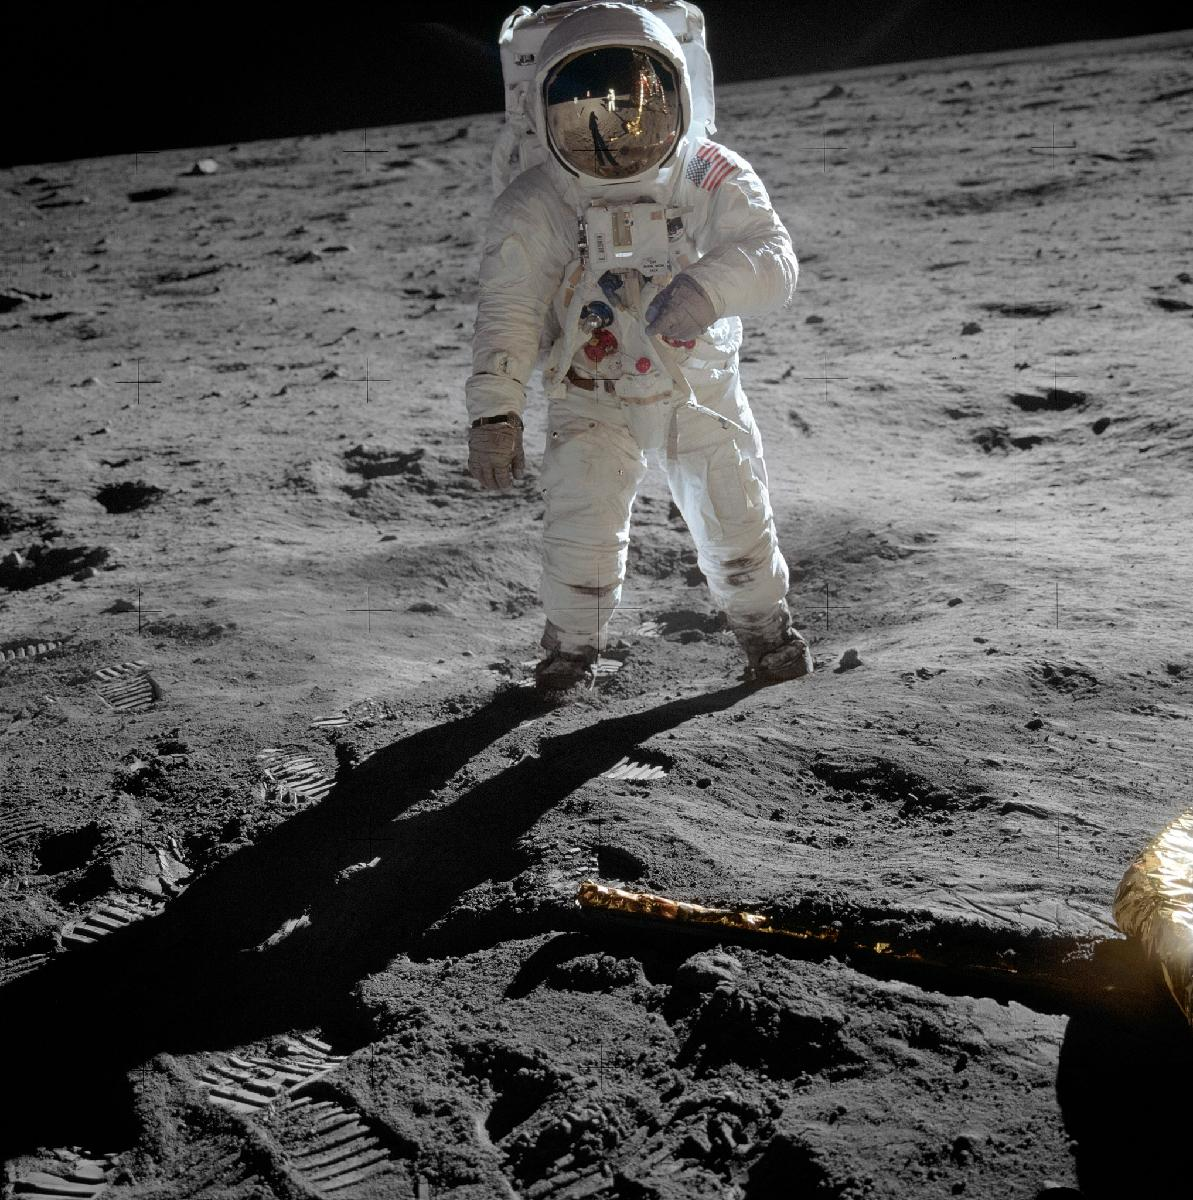 

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

`Icon that can be used`

  **Try**.   **Pro-tip**. ** Demonstration**.  **Reflect**. ** Application.**

## Apollo 11 Mission

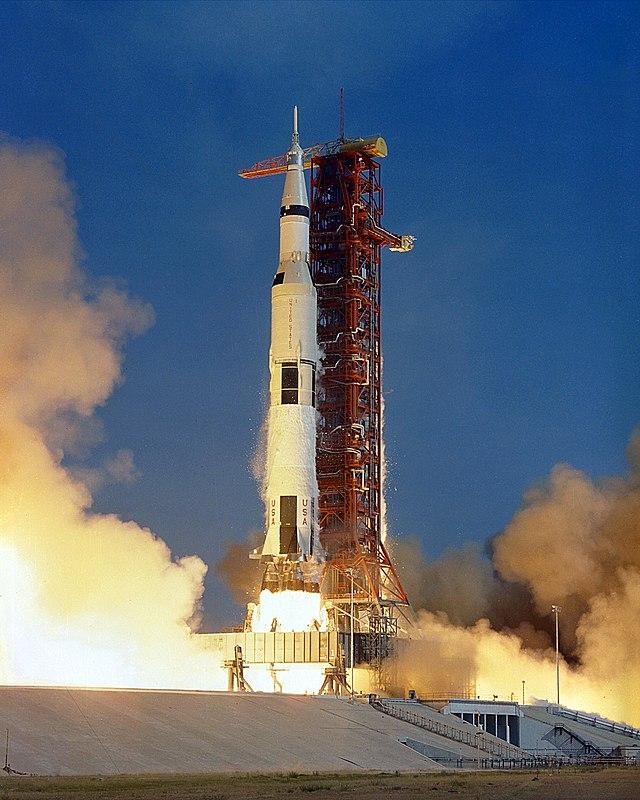The Apollo program was a spatial exploration program whose first mission started in the mid-1960s, the 11th mission (Apollo 11) was the first of six successfull mission to successfully bring men on the Moon. In this script, we will try to model the launch of the Apollo 11 Mission, using Control-Volume Method for accelerating Controle Volume. The results from the mathematical model will be compared to the real flight data gathered during the mission.

### Define the volume control

[Image of the control volume]

First we need to define the control volume

syms t0 t1 m0 m(t) y(t) v(t) a(t) g Isp mp0

The specific impulse is a common quantities that measure the efficiency of a reaction engine. In the case of rocket engine, the specific impulse is exactly proportional to the effective exhaust gas velocity: $V_e = g\cdot I_{sp}$, where $g$ is the acceleration due to gravity ( $g = 9.80665 \text{  m/s$^{2}$}$ ) and $I_{sp}$ is the specifice impulse.

  **Try**. **Compute the gas exhaust velocity out of the vulcan engine**

### Apply Conservation of Mass


$$\frac{\partial}{\partial t}\int_{CV}\rho dV + \int_{CS}\rho{\bf V}\cdot {\bf dA} = 0$$


  **Try**. **Plot the mass of the rocket with respect to time during phase 1**

m(t) = int( - mp0/(t1-t0), t) + m0

$$m(t) = m_{0}+\frac{{\mathrm{mp}}_{0}\,t}{t_{0}-t_{1}}$$

pm(t) = subs(m(t), {m0, mp0, t0, t1}, {2950000, 2050000, 0, 161})

$$pm(t) = 2950000-\frac{2050000\,t}{161}$$

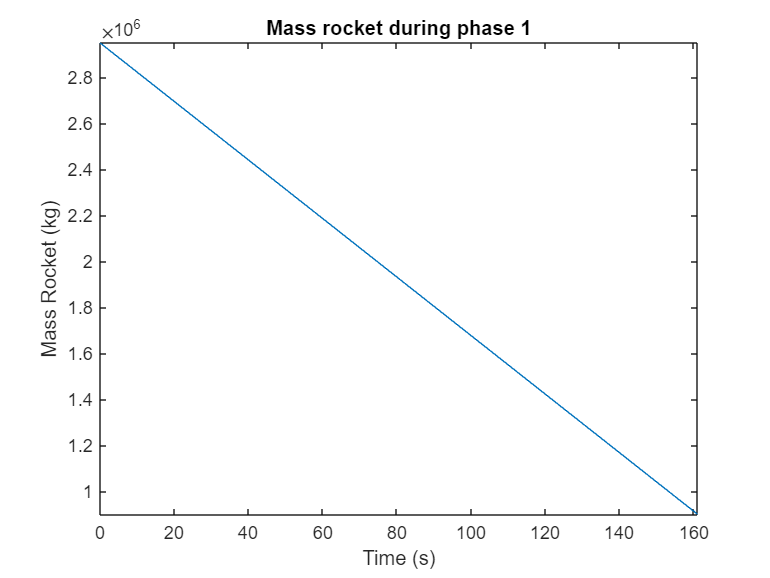

figure()
fplot(pm, [0 161])
xlabel("Time (s)")
ylabel("Mass Rocket (kg)")
title("Mass rocket during phase 1")

 **Reflect**. Large gas truck can deliver up to 11,600 gallons of gas, representing a mass of 50,000 kg of gas. The propellant used during the first phase of by the Saturn IV rocket was RP-1, an extremelly refined kerosene. During the 160s of phase 1, the rocket burns an equivalent of 20 large gas truck worth of kerosene and another 20 large gas truck worth of liquid oxygen.

### Apply Conservation of Momentum

[Equation for conservation of Momentum]

dzdt = @(t, z) [ z(2) ; V_e*M_e ./ (-M_e*t+M_SaturnIV0) - g];
V0 = [0.0; 0.0];
tspan = [0 160];
[t, V] = ode45(dzdt, tspan, V0);
figure()
yyaxis left
plot(t, V(:,1))
yyaxis right
plot(t, V(:,2))

## Compare Results to Real Flight Log Data From Apollo 11 Mission

load ApolloFlightLog.mat

tiledlayout(3,1)
nexttile
plot(Apollo.t, Apollo.Altitude/1000, 'SeriesIndex', 1, 'LineWidth', 2)
ylabel("Altitude (km)")
nexttile
plot(Apollo.t, Apollo.Velocity, 'SeriesIndex', 1, 'LineWidth', 2)
ylabel("Velocity (m/s)")
nexttile
plot(Apollo.t, Apollo.Acceleration, 'SeriesIndex', 1, 'LineWidth', 2)
ylabel('Acceleration (m/s^2)')
xlabel('Flight Time (s)')

 **Reflect**.  

## Causes of inacurracy

### Frictions Forces

load ApolloAero.mat
figure()
plot(AeroData, "Mach", "CAT", "LineWidth", 2)
xlabel("Mach Number (-)")
ylabel("Axial Froces Coefficient on Saturb IV (-)")

### Non-vertical flight path

 
load Trajectory.mat
uif = uifigure();
g = geoglobe(uif);
geoplot3(g,Flight.Lat,Flight.Lon,Flight.El,'y','HeightReference','terrain', 'LineWidth',3)

Plot the pitch during flight... we can correct for that

## Improvement of the model

### Correction for rocket flight path angle

### Correction for rocket drag

Cite the NASA report that gives the axial forces acting on the rocket as a function of the Mach number. Therefore, to compute this forces, we need to compute the Mach number of the 

Introduce some compressible flow concept.

Altitude = [0 11000 20000 32000 47000 51000 71000 84852];
StandardTemperature = [288.15 216.65 216.65 228.65 270.65 270.65 214.65 187.15];

Apollo.Tamb = interp1(Altitude, StandardTemperature, Apollo.Altitude, 'linear');

Dp/dz = - Rho*g = - P/(R*T)g

zspan = [Apollo.Altitude(1), Apollo.Altitude(end)];
P0 = 101325;
[z,P] = ode45(@(z,P) -P/(287*interp1(Altitude,StandardTemperature, z, 'linear')), zspan, P0);
Apollo.Pamb = interp1(z, P, Apollo.Altitude, 'pchip');

Rho = P / (R*T)

Apollo.Rho = Apollo.Pamb ./ (287 * Apollo.Tamb);
Apollo.SpeedOfSound = sqrt( 1.4 * 287 * Apollo.Tamb );
Apollo.Mach = Apollo.Velocity ./ Apollo.SpeedOfSound;


### Add the friction forces

## Conclusion

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

[⇦ Return to the navigation page](matlab: OpenOverview)